clc, clear all
%%plot stuff
beta = 0.1;
diam = 0.235;
Npts = 10;
t_max = 3.2 / beta;
T = linspace(0, t_max, t_max*Npts);
U = T .* beta;
R = 4.*[0.3960*cos(2.65*(U+1.4)) ; -0.99*sin(U+1.4)];
clf
hold on
plot(R(1,:), R(2,:),'k-', "Linewidth", 2)
%plot(R(1,:), R(2,:),'.', "Markersize", 10)
%%symbolic matlab to find other stuff


%%u = beat * t
syms t

ri=4*0.3960*cos(2.65*(t * beta+1.4));
rj=4*-0.99*sin(t * beta+1.4);
rk=0*t;
r=[ri,rj,rk];


v = diff(r, t);


$$v = \left(\begin{array}{ccc} -\frac{5247\,t\,\sin\left(\frac{53\,t}{200}+\frac{371}{100}\right)}{1250} & -\frac{99\,t\,\cos\left(\frac{t}{10}+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$


T_hat = (v ./ norm(v));
dT_hat = diff(T_hat, t);
N_hat = (dT_hat ./ norm(dT_hat));


%%
for i = 1:5:32
    t = i
    T_hat_eval = eval(subs(T_hat));
    N_hat_eval = eval(subs(N_hat));
    plot([R(1,t*Npts);R(1,t*Npts)+T_hat_eval(1)], [R(2,t*Npts+1);R(2,t*Npts)+T_hat_eval(2)], "r", "Linewidth", 1)
    plot([R(1,t*Npts);R(1,t*Npts)+N_hat_eval(1)], [R(2,t*Npts);R(2,t*Npts)+N_hat_eval(2)], "b", "Linewidth", 1)
end

t = 1

t = 6

t = 11

t = 16

t = 21

t = 26

t = 31

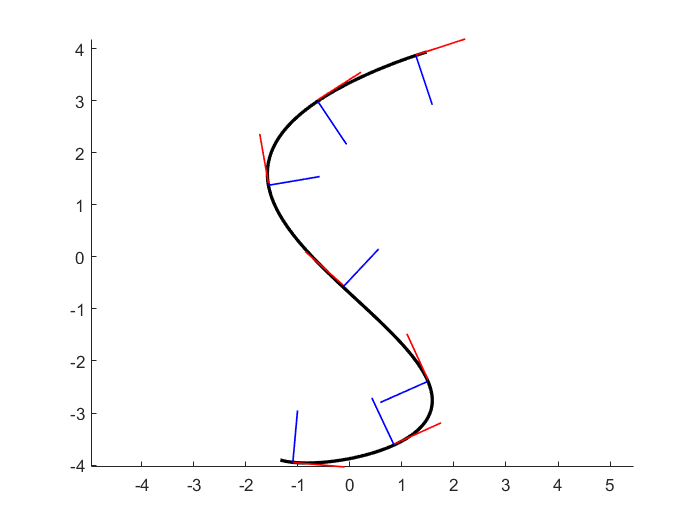

axis equal


omega = cross(T_hat, dT_hat);

V_right = norm(v) + omega(3) .* (diam/2);
V_left = norm(v) - omega(3) .* (diam/2);

figure(2)
clf
subplot(2,1,1)
fplot(V_right, [0,32])
xlim([0,32])
ylim([0,1])
subplot(2,1,2)
fplot(V_left, [0,32])
xlim([0,32])
ylim([0,1])

eval(subs(V_right, t, 1))

ans = 82.0375

eval(subs(V_left, t, 15))

ans = 82.0452

eval(subs(omega, t, 0))